# System parameter calculations

The goal of this script is to compute the dimensions of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection.

The stability, performance and effect of mass transfer of the long stroke is studied in the script: . The results of this study is deemed inaccurate due to unkown amount of friction. The performance of the second stage is leading in the final precision placement.

Therefore at last the short stroke performance is analysed such that the final performance is known

clear all; close all
%loading in functions and data
addpath("Spring Systems") 
addpath("Spiral pulley")
RealSprings = readtable('SupsensionSprings.xlsx');

#### Material constants

g = 9.81;
%alluminium
E_allu = 69E9; %
sigma_y_allu = 124E6; %steel https://www.steelinox.nl/nl/informatie/roestvast-staal-info
%https://www.gamma.nl/assortiment/plat-profiel-rvs-15x0-5x1000mm/p/B175454
E_steel = 190E9; %[Pa] elastic modulus of steel
sigma_y_steel = 250E6; %[Pa] yield stress steel
%pvc -> https://www.naeff.nl/nl/technische-datasheet/polyvinylchloride-pvc-u?n=2690_3
%https://www.praxis.nl/gereedschap-installatiemateriaal/ijzerwaren/profielen-platen/profielen/alberts-platte-stang-kunststof-wit-25x2mm-1m/5535075
E_pvc = 3000E6; %[Pa]
sigm_y_pvc = 58E6; %[Pa] %flow tension is used, as this is an underirable effect

#### System constants

m_load = 1.2;                              %[Kg] mass of the load (unused) 
m2 = 0.8;                 %[kg] unloaded mass .8
m1 =2.8;                  %[kg] loaded mass 2
m_s2 =1;                %[kg] second stage mass
sys_angle =28/180*pi;           %[rad] angle at which the mirror is located
t = 0.006;                  %[m] thickness of plate material that will be used for construction

#### Constraints

h_max = 0.4;               %[m] maximal height mass compensator
sf = 1.1;                  %safety margin 10%
add_safety_margin = true;
S1 = 140; %[mm] long stroke mechanism
S2 = 10; %[mm] short stroke mechanism

%making S1 and S2 into mm
S1 = S1*1e-3 %[mm]

S1 = 0.1400

S2 = S2*1e-3 %[mm]

S2 = 0.0100


if add_safety_margin %adding safety margin to desired strokes
    S1 = S1*sf;
    S2 = S2*sf;
end

# Long stroke

### parameters

R1 = 0.01;          %[m] inner radius -> constraint by material design of the pulley system
F1 = m1*g + m_s2*g;          %[N] initial load on the system
F2 = m2*g + m_s2*g;          %[N] second loading condition
h_mech = 5*t;      %[m] 5 plate material of space needed for construction
SR = 1/2;          %[] spring elongation ratio used to estimate spring properties

### Desired properties

stage1 = springsystem(F1,F2,S1,h_mech,h_max,SR, R1); %defining the spring system
stage1 = stage1.comp_sys(2)                          %computing the system properties

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              SR: 0.5000
               S: 0.1540
           h_max: 0.4000
          h_mech: 0.0300
              R1: 0.0100
            name: []
               n: []
          Fn_tot: []
              fn: []
      max_stroke: 0
        h_adjust: 0.0093
              R2: 0.0176
               k: 2.1204e+03
              L0: 0.1716
              L1: 0.0176
              L2: 0.0083
            Lmax: 0.3432
    springstroke: []


stage1.desired_properties()

    "k = 2120.43"

    "l0 = 171.5834"

    "fn = 171.5804"

    "Fn = 363.8242"



### Spring selection

In the function below all the springs in RealSprings.xlsx are evaluated and the best is selected for the given system

%setup
stage1springs = table(); %clearing the table value
n_springs_max = 2; %max number of springs that will be tested

for i = 1 : height(RealSprings)
    spring = RealSprings(i,:); %selecting spring
    for j = 1 :n_springs_max
        springs_sys = stage1.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        
        %appending data in to spring table 
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S1*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        stage1springs = [stage1springs ; spring]; %adding spring to result table
    end
end

%sorting
stage1springs = sortrows(stage1springs,'k','ascend'); %sorting for lowest stiffness
stage1springs = sortrows(stage1springs,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage1springs = 868×14 table
    Artikelcode     d       Dm      Lo       fn        Fn       R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k  
    ___________    ____    ____    _____    _____    ______    ____    ______________    _____    _    ______    _______    _____________    ____

    {'T1820' }      2.2    21.8      122      188       127    0.58    {'Verenstaal'}     5.37    2    160.41    59.742         true         1351
    {'TR2290'}      3.6    36.4      146      182    253

selected_spring = stage1springs(1,:); %selecting the best spring from the table above

%results
stage1.name = selected_spring.Artikelcode;
stage1.n = selected_spring.n;
stage1 = stage1.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              SR: 0.5000
               S: 0.1783
           h_max: 0.4000
          h_mech: 0.0300
              R1: 0.0100
            name: {'T1820'}
               n: 2
          Fn_tot: 254
              fn: 188
      max_stroke: 0.1604
        h_adjust: 0.0145
              R2: 0.0276
               k: 1351
              L0: 0.1220
              L1: 0.0276
              L2: 0.0131
            Lmax: 0.3279
    springstroke: 0.1604


In the system properties of the first stage it is favorable to have a lager spring stroke than the build stroke S. This means that the spring cannot overextend within the structure.

### Pulley design

The design of the pulley is done in a seperate script the resulting pulley shape can be found in:

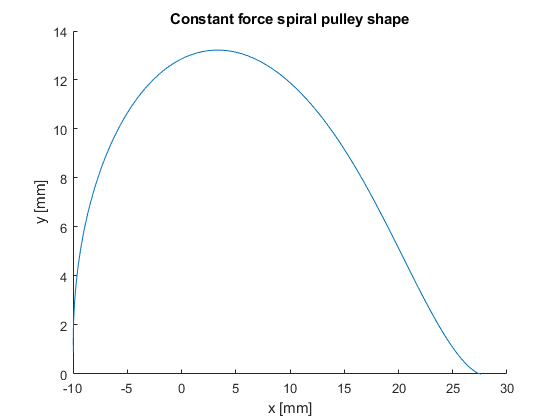

%setup
r1 = stage1.R1*1e3;
r2 = stage1.R2*1e3;
k = stage1.k*1e-3;
n_steps = 1000;

%setting F0
F0 = stage1.F1;
CF_spiral = spiral(r1,r2,F0,k); %creating spiral
CF_spiral = CF_spiral.Spiral_constant_Force(n_steps);
p1 = CF_spiral.plot_shape();

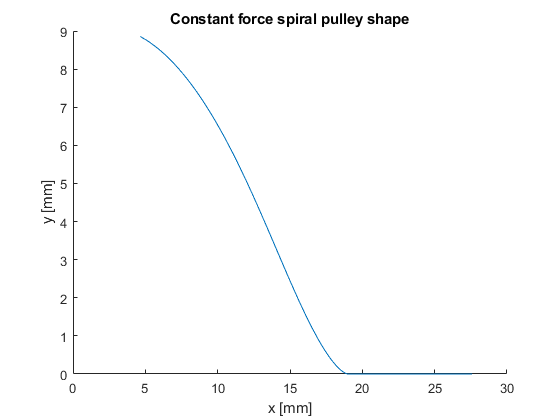


CF_spiral.save('spiral.xlsx') %saving results

%setting F0
F0 = stage1.F2;
CF_spiral = spiral(r1,r2,F0,k); %creating spiral
CF_spiral = CF_spiral.Spiral_constant_Force(n_steps);
p2 = CF_spiral.plot_shape();

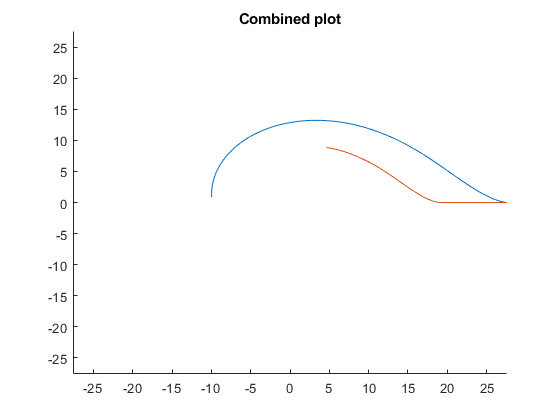


%combiningplot
figure()
hold on
f = findobj(p1,'type','line');
plot(f.XData,f.YData)
f = findobj(p2,'type','line');
plot(f.XData,f.YData)
xlim([-stage1.R2 stage1.R2]*1e3)
ylim([-stage1.R2 stage1.R2]*1e3)
title('Combined plot')

# Short stroke

The second stage consist out of two parts, the negative spring system and the positive spring system

### Design parameters

F1 = m1*g;              %[N] initial load on the system
F2 = m2*g;              %[N] second loading condition
reduction = 0.9;       %[]desired stiffness reduction ratio
n =4;                %[]number of leaf springs
SR = 1/2;              %[]spring ratio is lower with smaller sizes

#### System heights

h_heigh_control = S2*(1-reduction)      %[m] extra height needed to have height control on the output

h_heigh_control = 0.0011

h_plates = 2*t;                         %[m] height of the plates used in construction
h_adjustment_mech = 15e-3               %[m] height needed for adjustment mechanism

h_adjustment_mech = 0.0150

h_top_attachment = 10e-3;               %[m] height of the attachment on the top
h_spring_attachments = 0.5e-3 * 2;      %[m] height needed for spring attachments

%total height of the mechanims 
h_mech = h_plates + h_adjustment_mech + h_top_attachment + h_spring_attachments + h_heigh_control

h_mech = 0.0281

h_mech = h_mech*1.05 %adding build margin

h_mech = 0.0295



h_max = round(stage1.h_max - 2*stage1.R2 - stage1.max_stroke, 2); %maximum height short stroke
h2n = 30e-3; %[m] max heigh negative spring
h2p = h_max - h2n;      %[m] max height positive spring

%results
h_max, h2n, h2p        

h_max = 0.1800

h2n = 0.0300

h2p = 0.1500

## Desired positive spring

stage2p = springsystem(F1,F2,S2,h_mech,h2p,SR,0); %creating the secondstage positive spring system
stage2p = stage2p.comp_sys(2) %computing the system parameters

stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              SR: 0.5000
               S: 0.0110
           h_max: 0.1500
          h_mech: 0.0295
              R1: 0
            name: []
               n: []
          Fn_tot: []
              fn: []
      max_stroke: 0
        h_adjust: 0.0259
              R2: 0
               k: 756.9500
              L0: 0.0473
              L1: 0.0363
              L2: 0.0104
            Lmax: 0.0946
    springstroke: []


stage2p.desired_properties() %showing desired spring properties

    "k = 756.95"

    "l0 = 47.2876"

    "fn = 47.2877"

    "Fn = 35.7945"



### Second stage positive spring selection

%setup
stage2psprings = table(); %clearing the table value
n_springs_max = 2; %maximum allowed number of springs

%analyzing springs
for i = 1 : height(RealSprings)
    spring = RealSprings(i,:);
    for j = 1 : n_springs_max 
        springs_sys = stage2p.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        
        %appending spring properties 
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S2*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        
        %adding spring to result table
        stage2psprings = [stage2psprings ; spring];
    end
end

%sorting and selecting best spring
stage2psprings = sortrows(stage2psprings,'k','ascend'); %sorting for lowest stiffness
stage2psprings = sortrows(stage2psprings,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage2psprings = 868×14 table
    Artikelcode     d      Dm      Lo      fn      Fn      R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k  
    ___________    ___    ____    ____    ____    ____    ____    ______________    _____    _    ______    _______    _____________    ____

    {'TR810' }     0.9     9.1    36.5    57.6      20    0.29    {'RVS 302'   }     3.3     2    16.145    9.7848         true          694
    {'TR940' }       1      10    40.4    61.9    24.6    0.34    {'RV

selected_spring = stage2psprings(1,:); %selecting the best spring from the table above

%creating the spring system
stage2p.name = selected_spring.Artikelcode;
stage2p.n = selected_spring.n;
stage2p = stage2p.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties

stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              SR: 0.5000
               S: 0.0161
           h_max: 0.1500
          h_mech: 0.0295
              R1: 0
            name: {'TR810'}
               n: 2
          Fn_tot: 40
              fn: 57.6000
      max_stroke: 0.0161
        h_adjust: 0.0283
              R2: 0
               k: 694
              L0: 0.0365
              L1: 0.0396
              L2: 0.0113
            Lmax: 0.0922
    springstroke: 0.0180


again more spring stroke is desired such that the end stop of the negative spring will be hit first before the spring is overextended 

stage2p.S = S2; %setting stroke of the system

## Negative spring design

Below are the design parameters of the negative spring design

kn = round(stage2p.k*reduction) %desired negative spring stiffness

kn = 625

kn = 736*0.9

kn = 662.4000

E = E_steel; %selecting material properties
sigma_y = sigma_y_steel;
t = 0.0005; %[m] thickness plate steel
b = 0.01; %[m] widht plate steel

#### Viability short stroke 

Below are computation to estimate the viability of the system

I = t^3*b/12; %[m^4]  moment of inertia leaf spring
%L_desired = ( ( (S2)^2 * 53 * E *t)/(sigma_y*5/3) )^(1/3) %leaf spring length given the desired stroke
stage2n = negative_spring(E_steel,sigma_y,t,b,n,kn)

stage2n =   negative_spring with properties:

               E: 1.9000e+11
         sigma_y: 250000000
               t: 5.0000e-04
               b: 0.0100
               n: 4
              sm: 0.8700
    thread_pitch: 0.7000
               I: 1.0417e-13
               L: 0.1744
               k: 663
          uz_max: 0.0015
               S: 0.0182
      n_rotation: 2.1574


stage2n.S*1e3

ans = 18.2278

# Summary

stage1, stage2p, stage2n

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              SR: 0.5000
               S: 0.1783
           h_max: 0.4000
          h_mech: 0.0300
              R1: 0.0100
            name: {'T1820'}
               n: 2
          Fn_tot: 254
              fn: 188
      max_stroke: 0.1604
        h_adjust: 0.0145
              R2: 0.0276
               k: 1351
              L0: 0.1220
              L1: 0.0276
              L2: 0.0131
            Lmax: 0.3279
    springstroke: 0.1604


stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              SR: 0.5000
               S: 0.0110
           h_max: 0.1500
          h_mech: 0.0295
              R1: 0
            name: {'TR810'}
               n: 2
          Fn_tot: 40
              fn: 57.6000
      max_stroke: 0.0161
        h_adjust: 0.0283
              R2: 0
               k: 694
              L0: 0.0365
              L1: 0.0396
              L2: 0.0113
            Lmax: 0.0922
    springstroke: 0.0180


stage2n =   negative_spring with properties:

               E: 1.9000e+11
         sigma_y: 250000000
               t: 5.0000e-04
               b: 0.0100
               n: 4
              sm: 0.8700
    thread_pitch: 0.7000
               I: 1.0417e-13
               L: 0.1744
               k: 663
          uz_max: 0.0015
               S: 0.0182
      n_rotation: 2.1574


save('2stagesys.mat','stage1',"stage2p","stage2n") %saving results

## Short stroke performance

resulting_stiffness = stage2p.k - stage2n.k

resulting_stiffness = 31

stage2p.k*stage2p.S/2

ans = 3.8170

F2*0.05

ans = 0.3924

real_reduction = 1- resulting_stiffness/stage2p.k

real_reduction = 0.9553

max_stoorkracht = resulting_stiffness*S2/2

max_stoorkracht = 0.1705

stoorkracht_perc = max_stoorkracht / F1 * 100 %[perocent]

stoorkracht_perc = 0.6207

## Short stroke imperfection analysis

It is not possible to build to the micrometer perfectly, therefore we have to be sure that even given imperfect parts that are system is still **tunable **such that it is opertable and that given the build margin it is still stable.

threadpitch = 0.7; %[mm] thread pitch m4 bolt
displacement_per_rotation = threadpitch / (1 - real_reduction)

displacement_per_rotation = 15.6710

%thread pitch is the distance traveled by one rotation
springmargin =1.1; %spring max load and stiffness can be off by 10 percent
buildmargin = 5e-3; %[m] construction can be within 10 mm

### Lower positive stiffness and higher negative stiffness

The possitive spring can be off by 10 % -> however we can adjust the negative stiffness by adjusting L -> how accurate does this have to be?

stage2n.L = stage2n.L - buildmargin;
stage2n = stage2n.comp_stiff()

stage2n =   negative_spring with properties:

               E: 1.9000e+11
         sigma_y: 250000000
               t: 5.0000e-04
               b: 0.0100
               n: 4
              sm: 0.8700
    thread_pitch: 0.7000
               I: 1.0417e-13
               L: 0.1694
               k: 723
          uz_max: 0.0015
               S: 0.0182
      n_rotation: 2.1574


resulting_k =  stage2p.k - stage2n.k

resulting_k = -29

real_ratio = 1-resulting_k/stage2p.k

real_ratio = 1.0418